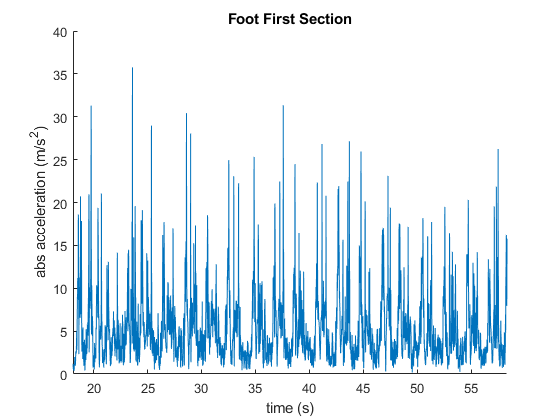

foot = csvread('form 2 foot.csv', 1,0);
pocket = csvread('form 2 pocket.csv', 1,0);
footTime = foot(:,1)';
footAbs = foot(:,5)';
pocketTime = pocket(:,1)';
pocketAbs = pocket(:,5)';

footStartOne = 1800;
footEndOne = 5800;
footTimeOne = footTime(footStartOne:footEndOne);
footAbsOne = footAbs(footStartOne:footEndOne);

footStartTwo = 7000;
footEndTwo = 11000;
footTimeTwo = footTime(footStartTwo:footEndTwo);
footAbsTwo = footAbs(footStartTwo:footEndTwo);

pocketStartOne = 1800;
pocketEndOne = 5500;
pocketTimeOne = pocketTime(pocketStartOne:pocketEndOne);
pocketAbsOne = pocketAbs(pocketStartOne:pocketEndOne);

pocketStartTwo = 7000;
pocketEndTwo = 10500;
pocketTimeTwo = pocketTime(pocketStartTwo:pocketEndTwo);
pocketAbsTwo = pocketAbs(pocketStartTwo:pocketEndTwo);

clf;
hold on
plot(footTimeOne, footAbsOne)
xlim([footTime(footStartOne),footTime(footEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot First Section')
hold off

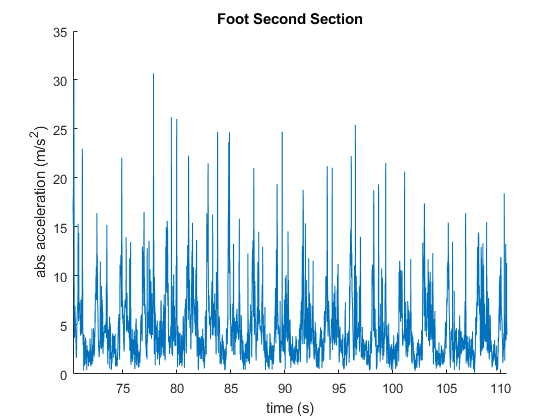


clf;
hold on
plot(footTimeTwo, footAbsTwo)
xlim([footTime(footStartTwo),footTime(footEndTwo)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot Second Section')
hold off

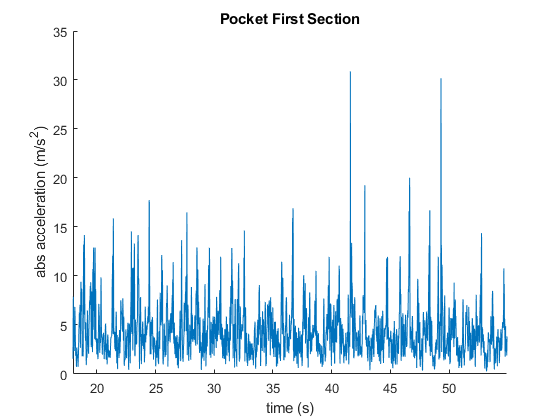


clf;
hold on
plot(pocketTimeOne, pocketAbsOne)
xlim([pocketTime(pocketStartOne),pocketTime(pocketEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Pocket First Section')
hold off

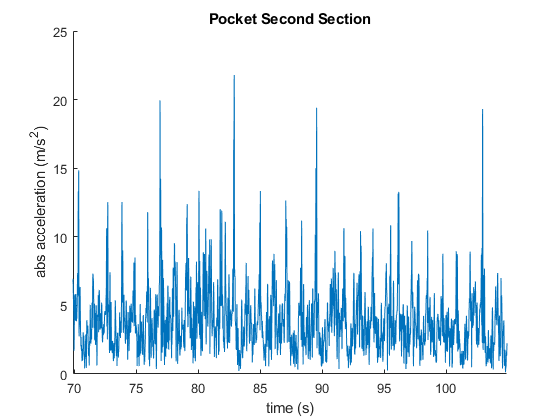


clf;
hold on
plot(pocketTimeTwo, pocketAbsTwo)
xlim([pocketTime(pocketStartTwo),pocketTime(pocketEndTwo)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Pocket Second Section')
hold off

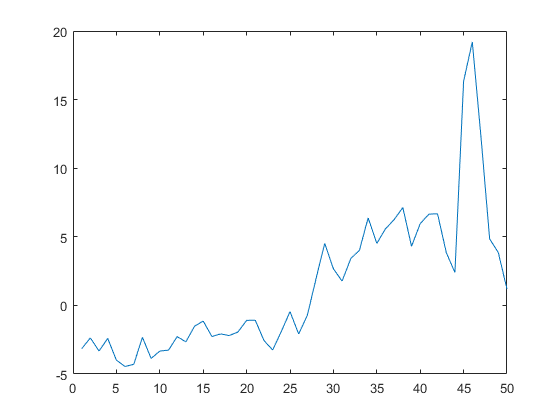


fftOne = fftshift(footAbsOne - mean(footAbsOne));
fftTwo = fftshift(footAbsTwo - mean(footAbsTwo));
fftDiff = fft(footAbsOne - footAbsTwo);
clf;
plot(real(fftOne(1:50)))

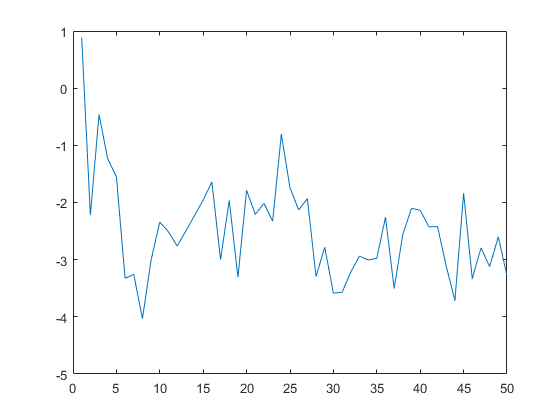

clf;
plot(real(fftTwo(1:50)))

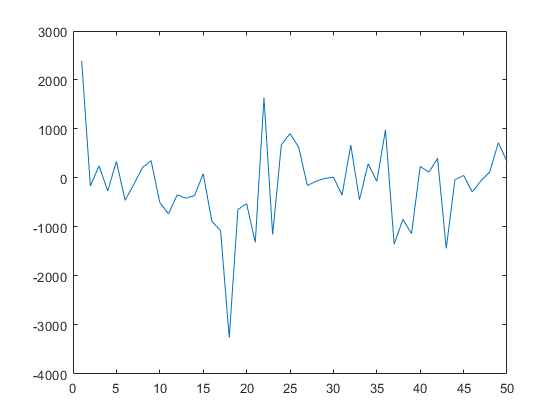

clf;
plot(real(fftDiff(1:50)))